# Preprocess Data for Building a Predictive Model

clearvars -except Data1
% load Data1.mat

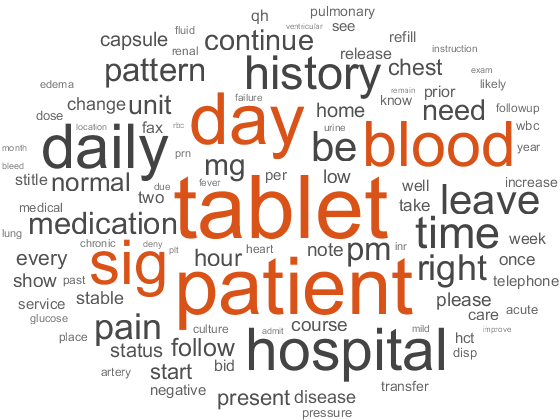

ans =   WordCloudChart with properties:

           WordData: [1×24626 string]
           SizeData: [1×24626 double]
    MaxDisplayWords: 100

  Show all properties


Y = Data1.LAPSE_FLAG; % response variable
td = preprocessText(Data1.Notes); % predictors
bag = bagOfWords(td);
bag = removeInfrequentWords(bag, 2); % remove uncommon words
wordcloud(bag)

M = tfidf(bag);
Y = categorical(Y);
tabulate(Y)

  Value    Count   Percent
      0     7704     80.34%
      1     1885     19.66%


cvp = cvpartition(Y, "Holdout", 0.2); % divide into training and testing
XTrain = M(training(cvp),:);
XTest = M(test(cvp),:);
YTrain = Y(training(cvp), :);
YTest = Y(test(cvp), :);

Next, we will build a model and test to ensure acceptable accuracy.

edit BuildModel_MIMIC_Demo_03.mlx

## Helper Functions

### Preprocess Text Data

function td = preprocessText(docs)
    td = tokenizedDocument(docs);
    td = erasePunctuation(td);
    td = removeStopWords(td);
    td = removeShortWords(td, 2);
    td = lower(td);
    td = regexprep(td, {'[0-9]', ':', '*','[', ']', 'admission', 'discharge', 'date', 'birth', 'first', 'last', 'name'}, '');
    td = normalizeWords(td, 'Style', 'lemma');
end

Copyright (c) 2020, The MathWorks, Inc.